clear
clc

K = 10;
T = 0.1;
zeta = sqrt(2)/2;
G = tf(K,[T^2 2*zeta*T 1])

G =
 
            10
  -----------------------
  0.01 s^2 + 0.1414 s + 1
 
Continuous-time transfer function.



T_d = 0.05;
G_d = c2d(G,T_d,'zoh')

G_d =
 
    0.9812 z + 0.7743
  ----------------------
  z^2 - 1.318 z + 0.4931
 
Sample time: 0.05 seconds
Discrete-time transfer function.



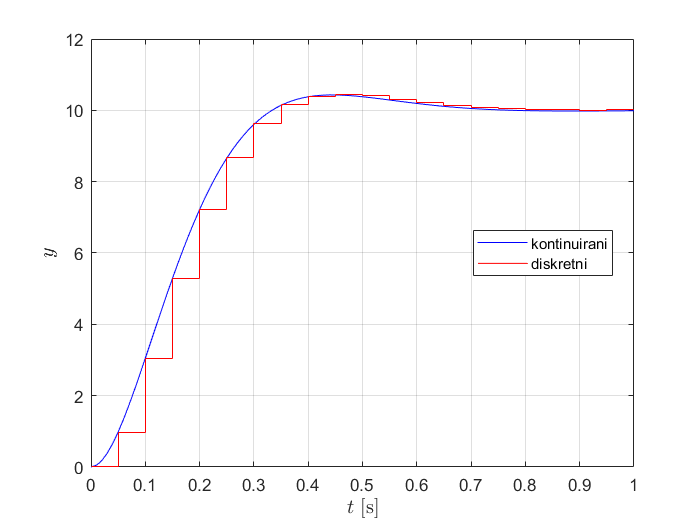


[num_d,den_d] = tfdata(G_d,'v');

% početni uvjeti
y_p1 = 0;
y_p2 = 0;
u_p1 = 0;
u_p2 = 0;

% broj točaka i priprema vektora za crtanje rezultata
N = 21;
y_d = zeros(N,1);
t_d = zeros(N,1);

% ulazna veličina je jedinični step
u = 1;

for i = 1:N
    % rekurzivna relacija:
    y = 1.318*y_p1 - 0.4931*y_p2 + num_d(2)*u_p1 + num_d(3)*u_p2;
    % osvjezavanje vrijednosti u proslim koracima
    y_p2 = y_p1;
    y_p1 = y;
    u_p2 = u_p1;
    u_p1 = u;
    % punjenje vektora za crtanje rezultata
    y_d(i) = y;
    t_d(i) = (i-1)*T_d;
end

[y_k,t_k] = step(G,(N-1)*T_d);
plot(t_k,y_k*u,'b')
grid on
hold on
stairs(t_d,y_d,'r')
hold off
xlabel('$t$ [s]','interpreter','latex','fontsize',12)
ylabel('$y$','interpreter','latex','fontsize',12)
legend('kontinuirani','diskretni','location','best')